# Kinetics, Bioreactors, and Chemostats (CSTR)

## Computational Tools Needed

MATLAB, Symbolic Math Toolbox

## Learning Objectives

- Using Symbolic Math Toolbox to obtain symbolic expressions reaction kinetics.

- Using MATLAB's ODE Solvers and "Solve ODE" Live Task to integrate rate equations in a batch bioreactor and visualize results

## Monod Equation

Typically, the growth of cells in a bioreactor can be summarized as 


$$\textrm{Cells}+\textrm{Substrate}\to \textrm{More}\;\textrm{cells}+\textrm{Product}\;$$


For exponential growth, Monod equation is the most commonly used expression:

$r_g =\mu C_C$                                              **(Equation 1)**

The specific cell growth rate is given by:

$\mu =\mu_{\max } \frac{C_s }{K_s +C_s }\;$                                  **(Equation 2)**

 **Exercise 1: **

Using MATLAB's Symbolic Math Toolbox, symbolically define Equation 1 and 2 in MATLAB, substitute Equation 2 into Equation 1 to derive **Monod Equation.**

**Step 1: **Define symbolic variables from Equation 1 and 2 as follows

% write your code here 



**Step 2: **Define Equation 1 and 2 in terms of symbolic variables defined in step 1. Example:

% write your code here 

**Step 3:  **In Equation, replace $\mu \;$with the right hand side of Equation 2. Store the result in monod-eq. Example:

% write your code here


**Step 4: **Diplay resulting equation. Example:

% write your code here


## Bacteria Growth in a Batch Reactor

Glucose fermentation to ethanol is achieved in a batch reactor using Saccharomyces cerevisiae. 

- Batch reactor with a constant volume, V 

- Flow rates into the reactor and out of the reactor are equal to 0. 

- Growth rate with inhibition

Mass balances for this case are as follows:

**Cell: **

$\frac{dC_c }{\textrm{dt}}=$ $\mu_{\max } \frac{C_c {\;C}_s }{K_s +C_s }$${\left(1-\frac{c_p }{c_p^* }\right)}^n -k_d C_c$                       **(Equation 3)**

**Substrate (growth phase)**

$\frac{dC_s }{\textrm{dt}}={-Y}_{s|c} \;\mu_{\max } \frac{C_c {\;C}_s }{K_s +C_s }{\left(1-\frac{c_p }{c_p^* }\right)}^n -{\textrm{mC}}_{c\;}$                **(Equation 4)**

**Product**

$\frac{dC_p }{\textrm{dt}}=Y_{p|c} \;\mu_{\max } \frac{C_c {\;C}_s }{K_s +C_s }{\left(1-\frac{c_p }{c_p^* }\right)}^n$                             **(Equation 5)**

 **Exercise 2: **Solve Equation 3, 4, 5 using MATLAB's [ode45 solver ](https://www.mathworks.com/help/matlab/ref/ode45.html)with the following values and plot the concentration of the cells, $C_c$, substrate $C_s$, product $C_p$ vs time.

**Step 1: **Initial conditions and time span are defined below. Values of the parameters are defined in the function where ODEs are defined.


% Initial Conditions for the differential equations

Cc0=5
Cs0= 250
Cp0=0;

% Time span
tspan = [0 30]; % Adjust the time span as needed


**Step 2:  **Define the ODE function, odefun with the set of differential equations given by Equation 3, 4, 5. Example:

% write your code here



**Step 3: **Construct a matrix from the initial conditions as follows 

% write your code here



**Step 4: **Call ode45 function to solve the set of differential equations with the time span and initial conditions defined in earlier steps. Example: 

% write your code here




**Step 5: **Visualize the ODE solution. We will plot ODE solutions for Equation 3, 4, 5 as parts of a subplot. Follow the example below:

% write your code here



**Step 6:** Open a new figure for the next exercise using figure

% write your code here



  ** Try: **

- What happens if you change the initial cell and substrate conditions?

- What happens if you change the timespan for the ODE solution?

- What happens if you use different ODE solvers? You can explore other ODE solvers [here.](https://www.mathworks.com/help/matlab/math/choose-an-ode-solver.html)

**Exercise 3: For this Exercise, Exercise 2 must be completed. It calls the functions from Exercise 2. **Solve the same problem using "Solve ODE" Live Task in the Live Editor. To add this Live Task, on Live Editor tab's toolstrip, click on "Task" dropdown and serch for "Solve ODE". Fill out "Live Task" as follows:

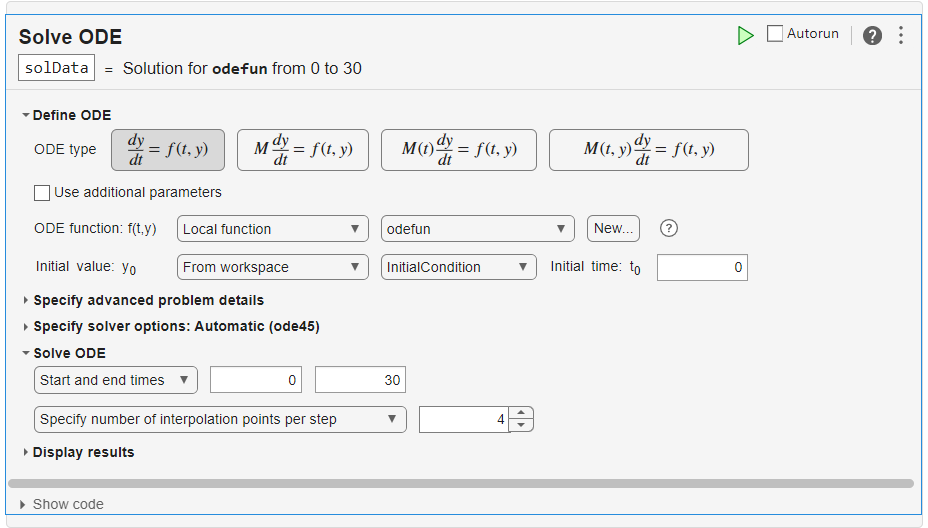

## **Chemostats (CSTR)**

- Let's consider the same problem, but this time, we will allow constant feed flow rate $\nu_{0\;}$ into and out of the reactor. The reactor volume is constant at $V\ldotp$ Using these, let's define the dilution rate as: $D=\frac{\nu_{0\;} }{V}$

- If no living cells are entering the reactor, set $C_{\textrm{cin}}$ = 0.

Mass balances for this case:


$$\textrm{Accumulation}=\textrm{In}-\textrm{Out}+\textrm{Generation}\;\textrm{or}\;\textrm{Depletion}$$


**Cell:**

$\frac{{\textrm{dC}}_c }{\textrm{dt}}={\textrm{DC}}_{\textrm{cin}} -{\textrm{DC}}_{c\;} +\left(r_g -r_d \right)=D\;\left(C_{\textrm{c0}} -C_c \right)\;\;+$$\mu_{\max } \frac{C_c {\;C}_s }{K_s +C_s }$${\left(1-\frac{c_p }{c_p^* }\right)}^n -k_d C_c$                  **                         (Equation 6)**

**Substrate:**

$\frac{{\textrm{dC}}_s }{\textrm{dt}}={\textrm{DC}}_{\sin \;} -{\textrm{DC}}_s +r_s =D\left(C_{\sin } -C_s \right)+r_s =D\left(C_{\textrm{s0}} -C_s \right){-Y}_{s|c} \;\mu_{\max } \frac{C_c {\;C}_s }{K_s +C_s }{\left(1-\frac{c_p }{c_p^* }\right)}^n -{\textrm{mC}}_{c\;}$                     **(Equation 7)**

**Product: **

$\frac{{\textrm{dC}}_p }{\textrm{dt}}={-\textrm{DC}}_{p\;} +r_{p\;\;} ={-\textrm{DC}}_p +Y_{p|c} \;\mu_{\max } \frac{C_c {\;C}_s }{K_s +C_s }{\left(1-\frac{c_p }{c_p^* }\right)}^n$                             **                                                 (Equation 8)**

**Exercise 4: **Modify the code for Exercise 2 to solve the Equations 6, 7, 8 with the same parameters as Exercise 2. For dilution, add a slider that ranges from 0 to 0.6 with 0.01 increments. You should define the variable for Dilution, D, inlet substrate and cell concentrations $C_{\textrm{cin}\;} ,C_{\sin }$ and other parameters in the function where you define the differential equations. 

**Step 1:  **Create a modified ODE function to account for the new parameters and dilution rate and define the new differential equations. Example:

%  write your code here


**Step 2: **Call an ODE solver function with the newly defined ODE. Time span and Initial Condition were defined previously, reuse them. Refer to Exercise 2, step 4 if you need an example.

% write your code here


**Step 3: **Plot your results like you did in Exercise 2, step 5. 

% write your code here


  ** Try: **

- What happens if you change the initial cell and substrate conditions? 

- What happens if you change the inlet cell and substrate concentrations?

- If you set D=0 i.e. no flow, do you get the same results as Exercise 2 and 3 results? 

- What happens if the dilution rate, D is high? What happens if the dilution rate, D is low?  

- What happens if the cell death rate is 0?

**Exercise 5: **Define Equation 6  symbolically (first part, i.e. $\frac{{\textrm{dC}}_c }{\textrm{dt}}=-{\textrm{DC}}_{c\;} +\left(r_g -r_d \right)$ with no living cells entering) using MATLAB's Symbolic Math Toolbox. Then, assume that it is a steady-state operation, i.e. $\frac{{\textrm{dC}}_c }{\textrm{dt}}=0$. Assume death rate, $r_d$ is 0.Use $r_g =\mu \;C_c$  for cell growth. How is dilution, D related to the specific growth rate, $\mu \;$? 

**Step 1: **Symbolically define the variables to be used as follows:

% write your code here


**Step 2: **Symbolically define Equation 6 as shown in example below:

% write your code here


**Step 3: **Set $\frac{{\textrm{dC}}_c }{\textrm{dt}}=0$ in Equation 6 for steady state as shown in the example.

% write your code here


**Step 4:** In the equation obtained in Step 3, set $r_d =0$ as shown in the example

% write your code here


**Step 5:** In the equation obtained in Step 4, set $r_g =\mu \;C_c$

% write your code here


**Step 6: **Assume $C_c \left(t\right)\not= 0$ and simplify the equation obtained in Step 5 following the example below.

% write your code here


### **Things to Consider:**

- At steady-state, $D=\mu \;$i.e. the specific growth rate of the cells can be controlled by controlling the dilution rate, $D=\frac{\nu_{0\;} }{V}$ 

- If the dilution rate is increased such that $D>\mu \;$, eventually, there will be a point where $C_c =0$, that's called **wash-out.  **The other extreme for the dilution rate is when the rate of cell production is maximum.

## **References**

[1] Fogler, H. Scott. Elements of Chemical Reaction Engineering. Prentice Hall, 2006.

[2][ Fogler, H. Scott Lecture Notes ](https://websites.umich.edu/~elements/6e/lectures/umich.html)